close('all'); clear; clc;
setmadsympath();
sympref("FloatingPointOutput",false);

## Geometry

The Sharp model considers a left-handed frame (North, West, Down).

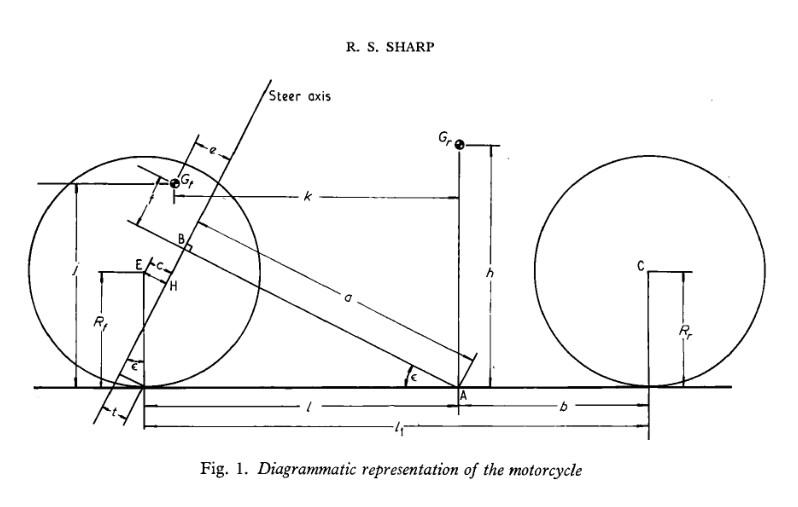

Create the caster frame:

caster = newParameters('varepsilon');
N = Frame;
Nc = N.orientNew('y',caster);

Solve for the front wheelbase $l$:

[a,an,l] = newParameters('a','a_n','l');
Pa = Point;
Pb = Pa.locateNew(a*Nc.x);
eqn = cos(caster) - a/(l + an/cos(caster));
l = solve(eqn,l);

Locate the front wheel center $E$:

rf = newParameters('r_f');
E = Pa.locateNew(l*N.x - rf*N.z);
rE = E.posFrom;
pprint(rE)

$$\left[\begin{array}{c} \frac{a-a_{n}}{c_{\varepsilon }}\\ 0\\ -r_{f} \end{array}\right]$$

Now locate the front wheel center relative to the intersection between the front chassis chord and the steering axis:

rBE = E.posFrom(Pb,Nc);
rBE = simplify(expand(rBE));

lx_sub = rBE(1);
pprint(lx_sub);

$$r_{f}\,s_{\varepsilon }-a_{n}$$


lz_sub = rBE(3);
pprint(lz_sub);

$$-\frac{r_{f}\,{c_{\varepsilon }}^{2}-a\,s_{\varepsilon }+a_{n}\,s_{\varepsilon }}{c_{\varepsilon }}$$

Now solve for the front chassis chord $a$ and the height $f$ of the front chassis mass center in the caster frame to obtain a simplifying substitution for $l_{z}$:

[e,f,j,k] = newParameters('e','f','j','k');
Gfa = Pa.locateNew(k*N.x - j*N.z);
Gh = Pb.locateNew(e*Nc.x + f*Nc.z);
sol_af = solve(Gh.posFrom(Gfa),[a,f]);

## Kinematics

t = sym('t');
N = Frame;
O = Point;

### Sharp origin

Orientation : 

yaw = dynamicVariable("psi");
Nyaw = N.orientNew('z',yaw);

Position :

[px,py] = dynamicVariables('x','y');
Pa = O.locateNew(px.*N.x + py.*N.y);

### Rear chassis

Orientation:

lean = dynamicVariable("varphi");
Nlean = Nyaw.orientNew('x',lean);
pprint(Nlean.dcm)

$$\left[\begin{array}{ccc} c_{\psi } & -c_{\phi }\,s_{\psi } & s_{\psi }\,s_{\phi }\\ s_{\psi } & c_{\psi }\,c_{\phi } & -c_{\psi }\,s_{\phi }\\ 0 & s_{\phi } & c_{\phi } \end{array}\right]$$

Position:

h = newParameters('h');
Gb = Pa.locateNew(-h.*Nlean.z);
pprint(Gb.posFrom)

$$\left[\begin{array}{c} x-h\,s_{\psi }\,s_{\phi }\\ y+c_{\psi }\,h\,s_{\phi }\\ -c_{\phi }\,h \end{array}\right]$$

### Rear wheel

Orientation:

pitch_r = dynamicVariable("theta_r");
Npitch_r = Nlean.orientNew('y',pitch_r);
pprint(Npitch_r.dcm);

$$\left[\begin{array}{ccc} c_{\psi }\,c_{\theta ,r}-s_{\psi }\,s_{\theta ,r}\,s_{\phi } & -c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\theta ,r}+c_{\theta ,r}\,s_{\psi }\,s_{\phi }\\ c_{\theta ,r}\,s_{\psi }+c_{\psi }\,s_{\theta ,r}\,s_{\phi } & c_{\psi }\,c_{\phi } & s_{\psi }\,s_{\theta ,r}-c_{\psi }\,c_{\theta ,r}\,s_{\phi }\\ -c_{\phi }\,s_{\theta ,r} & s_{\phi } & c_{\theta ,r}\,c_{\phi } \end{array}\right]$$

Position:

[b,rr] = newParameters('b','r_r');
Gr = Pa.locateNew(-b.*Nlean.x -rr.*Nlean.z);
pprint(Gr.posFrom)

$$\left[\begin{array}{c} x-b\,c_{\psi }-r_{r}\,s_{\psi }\,s_{\phi }\\ y-b\,s_{\psi }+c_{\psi }\,r_{r}\,s_{\phi }\\ -c_{\phi }\,r_{r} \end{array}\right]$$

### Rear contact point

Cr = Gr.locateNew(rr*Nlean.z);
rWrCr = Cr.posFrom(Gr,Npitch_r);
pprint(rWrCr)

$$\left[\begin{array}{c} -r_{r}\,s_{\theta ,r}\\ 0\\ c_{\theta ,r}\,r_{r} \end{array}\right]$$

### Front chassis

Orientation:

Ncaster = Nlean.orientNew('y',caster);
steer = dynamicVariable("delta");
Nsteer = Ncaster.orientNew('z',steer);
pprint(Nsteer.dcm())

$$\left[\begin{array}{ccc} c_{\delta }\,c_{\psi }\,c_{\varepsilon }-c_{\phi }\,s_{\delta }\,s_{\psi }-c_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon } & s_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon }-c_{\psi }\,c_{\varepsilon }\,s_{\delta }-c_{\delta }\,c_{\phi }\,s_{\psi } & c_{\psi }\,s_{\varepsilon }+c_{\varepsilon }\,s_{\psi }\,s_{\phi }\\ c_{\psi }\,c_{\phi }\,s_{\delta }+c_{\delta }\,c_{\varepsilon }\,s_{\psi }+c_{\delta }\,c_{\psi }\,s_{\phi }\,s_{\varepsilon } & c_{\delta }\,c_{\psi }\,c_{\phi }-c_{\varepsilon }\,s_{\delta }\,s_{\psi }-c_{\psi }\,s_{\delta }\,s_{\phi }\,s_{\varepsilon } & s_{\psi }\,s_{\varepsilon }-c_{\psi }\,c_{\varepsilon }\,s_{\phi }\\ s_{\delta }\,s_{\phi }-c_{\delta }\,c_{\phi }\,s_{\varepsilon } & c_{\delta }\,s_{\phi }+c_{\phi }\,s_{\delta }\,s_{\varepsilon } & c_{\phi }\,c_{\varepsilon } \end{array}\right]$$

Position:

Pb = Pa.locateNew(a.*Ncaster.x);
Gh = Pb.locateNew(e.*Nsteer.x + f.*Nsteer.z);

### Front wheel

Orientation:

yaw_f = dynamicVariable("psi_f");
Nyaw_f = N.orientNew('z',yaw_f);

lean_f = dynamicVariable("varphi_f");
Nlean_f = Nyaw_f.orientNew('x',lean_f);

pitch_f = dynamicVariable("theta_f");
Npitch_f = Nlean_f.orientNew('y',pitch_f);

pprint(Npitch_f.dcm)

$$\left[\begin{array}{ccc} c_{\psi ,f}\,c_{\theta ,f}-s_{\psi ,f}\,s_{\theta ,f}\,s_{\phi ,f} & -c_{\phi ,f}\,s_{\psi ,f} & c_{\psi ,f}\,s_{\theta ,f}+c_{\theta ,f}\,s_{\psi ,f}\,s_{\phi ,f}\\ c_{\theta ,f}\,s_{\psi ,f}+c_{\psi ,f}\,s_{\theta ,f}\,s_{\phi ,f} & c_{\psi ,f}\,c_{\phi ,f} & s_{\psi ,f}\,s_{\theta ,f}-c_{\psi ,f}\,c_{\theta ,f}\,s_{\phi ,f}\\ -c_{\phi ,f}\,s_{\theta ,f} & s_{\phi ,f} & c_{\theta ,f}\,c_{\phi ,f} \end{array}\right]$$

Position:

[lx,lz] = newParameters("l_x","l_z");
rBWf = lx.*Nsteer.x + lz.*Nsteer.z;
Gf = Pb.locateNew(rBWf);

### Front contact point

Cf = Gf.locateNew(rf.*Nlean_f.z);
rWfCf = Cf.posFrom(Gf,Npitch_f);
pprint(rWfCf)

$$\left[\begin{array}{c} -r_{f}\,s_{\theta ,f}\\ 0\\ c_{\theta ,f}\,r_{f} \end{array}\right]$$

## Rigid bodies

### Rear chassis

mr = newParameters('m_r');

names = {
    'I_rx';
    'I_ry';
    'I_rz'
    };

[Irx,Iry,Irz] = newParameters(names{:});
Crxz = newParameters("C_rxz");
Ir = inertia(Irx,Iry,Irz,'Ixz',Crxz);
Bb = Body(Nlean,Gb,Ir,mr);

### Rear wheel

iry = newParameters('i_ry');
Irw = inertia(0,iry,0);
Br = Body(Npitch_r,Gr,Irw,0);

### Front chassis

names = {
    'm_f';
    'I_fx';
    'I_fz'
    };

[mf,Ifx,Ifz] = newParameters(names{:});
If = inertia(Ifx,0,Ifz);
Bh = Body(Nsteer,Gh,If,mf);

### Front wheel

ify = newParameters('i_fy');
Ifw = inertia(0,ify,0);
Bf = Body(Npitch_f,Gf,Ifw,0);

## Generalized coordinates

qall = [
    yaw;
    lean;
    steer;
    px;
    py;
    pitch_r;
    yaw_f;
    lean_f;
    pitch_f
    ];

qdep = [
    yaw_f;
    lean_f
    ];

v = sym("V");
q0 = zeros(size(qall));
qd0 = [0,0,0,v,0,-v/rr,0,0,-v/rf];

q = GeneralizedCoordinates(qall,qdep,q0,qd0);

## Generalized speeds

names = {
    'omega_psi';
    'omega_varphi';
    'omega_delta';
    'v_x';
    'v_y'
    };

uind = dynamicVariables(names{:});
udep = dynamicVariables('u',6:9);

uall = [
    uind;
    udep
    ];

u0 = zeros(numel(uall),1,"sym");
u0(4) = v;

u = GeneralizedCoordinates(uall,udep,u0);

## Auxiliary speeds

[Yr,Yf] = dynamicVariables("Y_r","Y_f");
Y0 = zeros(2,1);
Y = GeneralizedCoordinates([Yr,Yf].',[],Y0);

## Holonomic constraints

spin_x = Nsteer.y(1) - Nlean_f.y(1);
spin_z = Nsteer.y(3) - Nlean_f.y(3);

hc = [
    spin_z;
    spin_x
    ];

hc = simplify(expand(hc));

pprint(hc)

$$\left[\begin{array}{c} c_{\delta }\,s_{\phi }-s_{\phi ,f}+c_{\phi }\,s_{\delta }\,s_{\varepsilon }\\ c_{\phi ,f}\,s_{\psi ,f}-c_{\delta }\,c_{\phi }\,s_{\psi }-c_{\psi }\,c_{\varepsilon }\,s_{\delta }+s_{\delta }\,s_{\psi }\,s_{\phi }\,s_{\varepsilon } \end{array}\right]$$

## Nonholonomic constraints

no_slip_r = noslip(Br,rWrCr,Nyaw);
no_slip_f = noslip(Bf,rWfCf,Nyaw_f);

nhc = [
    N.x.'*no_slip_r;
    N.x.'*no_slip_f
    ];

nhc = simplify(expand(nhc));
cons = ConstraintEquations(q,hc,nhc);

## Kinematic equations

Ta = Pose(Nyaw,Pa);
Va = Twist(Ta).vector();

kdes = [
    u.All(1:3) - diff(q.All(1:3))
    u.All(4:5) - Va(4:5);
    ];

pprint(kdes);

$$\left[\begin{array}{c} \omega_{\psi }-\dot{\psi }\\ \omega_{\phi }-\dot{\phi }\\ \omega_{\delta }-\dot{\delta }\\ v_{x}-c_{\psi }\,\dot{x}-s_{\psi }\,\dot{y}\\ v_{y}-c_{\psi }\,\dot{y}+s_{\psi }\,\dot{x} \end{array}\right]$$

## Tire equations

TCr = Pose(Nyaw,Cr);
TCf = Pose(Nyaw_f,Cf);

VCr = Twist(TCr).vector();
vCr = VCr(4:5);

VCf = Twist(TCf).vector();
vCf = VCf(4:5);

rl = newParameters('sigma');

names = {
    'C_r1';
    'C_r2';
    'C_f1';
    'C_f2'
    };

[Cr1,Cr2,Cf1,Cf2] = newParameters(names{:});

slip_r = atan(vCr(2)/vCr(1));
slip_f = atan(vCf(2)/vCf(1));

eqYr = vCr(1)*(Yr + Cr1*slip_r - Cr2*lean);
eqYf = vCf(1)*(Yf + Cf1*slip_f - Cf2*lean_f);
eqY = [
    rl*diff(Yr,t) + eqYr;
    rl*diff(Yf,t) + eqYf
    ];

## Forces and moments

### Rear tire

Zr = newParameters('Z_r');
Br.applyForce(Nyaw,Cr,Yr*N.y + Zr.*N.z);

### Front tire

Zf = newParameters('Z_f');
Bf.applyForce(Nyaw_f,Cf,Yf.*N.y + Zf.*N.z);

### Steering torque

Msteer = dynamicVariable("tau_delta");
Csteer = newParameters('C_delta');
Mz = (Msteer - Csteer*diff(steer,t)).*N.z;
Bh.applyMoment(Nsteer,Mz);
Bb.applyMoment(Nsteer,-Mz);

### Gravity

bodies = [
    Bb;
    Br;
    Bh;
    Bf
    ];

g = newParameters('g');
fp = @(b)b.MassCenter;
fFg = @(b)(b.Mass*g).*N.z;
fg = @(b)b.applyForce(N,fp(b),fFg(b));
arrayfun(fg,bodies);

## Equations of motion

X = StateVector(q,u,Y);
F = GeneralizedCoordinates(Msteer,[],0,0);
eom = appellsMethod(X,kdes,bodies,F,cons,eqY);

## Linearized equations of motion

eoml = linearize(eom);
eoml = simplify(eoml);

### Geometric simplifications

ovals = [lx,lz];
nvals = [lx_sub,lz_sub];
nvals = simplify(expand(nvals));

M = subs(eoml.MassMatrix,ovals,nvals);
H = subs(eoml.ForcingMatrix,ovals,nvals);

ovals = [a,f];
nvals = [sol_af.a,sol_af.f];
nvals = simplify(expand(nvals));

M = subs(M,ovals,nvals);
H = subs(H,ovals,nvals);
G = eoml.InputMatrix;

ovals = j*sin(caster);
nvals = a - cos(caster)*k + e;

H = subs(H,ovals,nvals);

## Sharp's equations

xd = diff(eoml.States.All,t);
xind = eoml.States.Independent;
eqns = M*xd - H*xind - G*eoml.Inputs.All;

x_sharp = [
    lean;
    steer;
    u.Independent([1:3,5])
    Yr;
    Yf
    ];

P = jacobian(eoml.States.All,x_sharp);
eqns_sharp = P.'*eqns;

[Ms,fs] = massMatrixForm(eqns_sharp,x_sharp);
[Hs,gs] = equationsToMatrix(fs,x_sharp);
Gs = jacobian(-gs,eoml.Inputs.All);

xs = GeneralizedCoordinates(x_sharp);
eoms = LinearizedMotionEquations(xs,Ms,Hs,Gs,F);
eoms = simplify(eoms);
disp(eoms)

States : 


$$\left[\begin{array}{cccccccc} \phi & \delta & \omega_{\psi } & \omega_{\phi } & \omega_{\delta } & v_{y} & Y_{r} & Y_{f} \end{array}\right]$$

Mass Matrix : 


$$\left[\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & I_{\mathrm{fz}}+I_{\mathrm{rz}}+I_{\mathrm{fx}}\,{s_{\varepsilon }}^{2}-I_{\mathrm{fz}}\,{s_{\varepsilon }}^{2}+k^{2}\,m_{f} & C_{\mathrm{rxz}}-\frac{I_{\mathrm{fx}}\,\sin\left(2\,\varepsilon \right)}{2}+\frac{I_{\mathrm{fz}}\,\sin\left(2\,\varepsilon \right)}{2}+j\,k\,m_{f} & I_{\mathrm{fz}}\,c_{\varepsilon }+e\,k\,m_{f} & k\,m_{f} & 0 & 0\\ 0 & 0 & C_{\mathrm{rxz}}-\frac{I_{\mathrm{fx}}\,\sin\left(2\,\varepsilon \right)}{2}+\frac{I_{\mathrm{fz}}\,\sin\left(2\,\varepsilon \right)}{2}+j\,k\,m_{f} & I_{\mathrm{fx}}+I_{\mathrm{rx}}-I_{\mathrm{fx}}\,{s_{\varepsilon }}^{2}+I_{\mathrm{fz}}\,{s_{\varepsilon }}^{2}+h^{2}\,m_{r}+j^{2}\,m_{f} & I_{\mathrm{fz}}\,s_{\varepsilon }+e\,j\,m_{f} & h\,m_{r}+j\,m_{f} & 0 & 0\\ 0 & 0 & I_{\mathrm{fz}}\,c_{\varepsilon }+e\,k\,m_{f} & I_{\mathrm{fz}}\,s_{\varepsilon }+e\,j\,m_{f} & m_{f}\,e^{2}+I_{\mathrm{fz}} & e\,m_{f} & 0 & 0\\ 0 & 0 & k\,m_{f} & h\,m_{r}+j\,m_{f} & e\,m_{f} & m_{f}+m_{r} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \sigma & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \sigma \end{array}\right]$$

Forcing Matrix : 


$$\left[\begin{array}{cccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & -V\,m_{f}\,\left(k\,{s_{\varepsilon }}^{2}-c_{\varepsilon }\,j\,s_{\varepsilon }+a\,c_{\varepsilon }+c_{\varepsilon }\,e\right) & \frac{V\,i_{\mathrm{fy}}}{r_{f}}+\frac{V\,i_{\mathrm{ry}}}{r_{r}} & \frac{V\,i_{\mathrm{fy}}\,s_{\varepsilon }}{r_{f}} & 0 & -b & \frac{a-a_{n}}{c_{\varepsilon }}\\ g\,\left(j\,m_{f}\,{c_{\varepsilon }}^{2}-k\,m_{f}\,s_{\varepsilon }\,c_{\varepsilon }+h\,m_{r}+a\,m_{f}\,s_{\varepsilon }+e\,m_{f}\,s_{\varepsilon }\right) & e\,g\,m_{f}-Z_{f}\,a_{n} & V\,c_{\varepsilon }\,k\,m_{f}\,s_{\varepsilon }-\frac{V\,i_{\mathrm{fy}}}{r_{f}}-\frac{V\,i_{\mathrm{ry}}}{r_{r}}-V\,{c_{\varepsilon }}^{2}\,j\,m_{f}-V\,a\,m_{f}\,s_{\varepsilon }-V\,e\,m_{f}\,s_{\varepsilon }-V\,h\,m_{r} & 0 & -\frac{V\,c_{\varepsilon }\,i_{\mathrm{fy}}}{r_{f}} & 0 & 0 & 0\\ e\,g\,m_{f}-Z_{f}\,a_{n} & -s_{\varepsilon }\,\left(Z_{f}\,a_{n}-e\,g\,m_{f}\right) & -V\,e\,m_{f}-\frac{V\,i_{\mathrm{fy}}\,s_{\varepsilon }}{r_{f}} & \frac{V\,c_{\varepsilon }\,i_{\mathrm{fy}}}{r_{f}} & -C_{\delta } & 0 & 0 & -a_{n}\\ 0 & 0 & -V\,\left(m_{f}+m_{r}\right) & 0 & 0 & 0 & 1 & 1\\ C_{\mathrm{r2}}\,V & 0 & C_{\mathrm{r1}}\,b & 0 & 0 & -C_{\mathrm{r1}} & -V & 0\\ C_{\mathrm{f2}}\,V & V\,\left(C_{\mathrm{f1}}\,c_{\varepsilon }+C_{\mathrm{f2}}\,s_{\varepsilon }\right) & -\frac{C_{\mathrm{f1}}\,\left(a-a_{n}\right)}{c_{\varepsilon }} & 0 & C_{\mathrm{f1}}\,a_{n} & -C_{\mathrm{f1}} & 0 & -V \end{array}\right]$$

Input Matrix : 


$$\left[\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 1\\ 0\\ 0\\ 0 \end{array}\right]$$

Inputs : 


$$\tau_{\delta }$$

## State space

matlabFunction(eoms,"sharpMotorcycle");

## Linear analysis

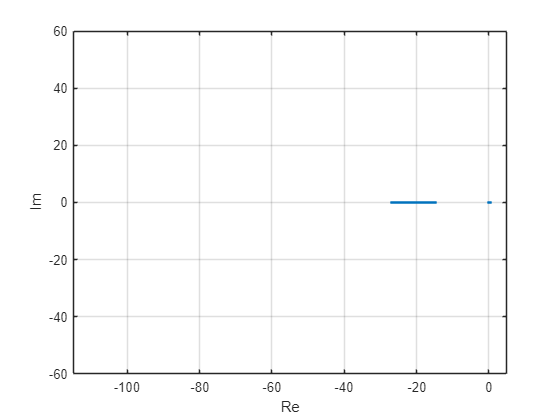

params = sharpMotorcycle1971Parameters().list();
fp = @(vx)[params(1:end-1);vx;params(end)];
x0 = zeros(8,1);
fss = @(vx)sharpMotorcycleStateSpace(x0,fp(vx));

vx = (1/3.6).*linspace(1,220,500).';
sys = arrayfun(fss,vx,"uniform",0);

fpoles = @(sys)eig(sys.a);
p = cell2mat(cellfun(fpoles,sys,'uniform',0));

fig = figure();
axe = axes(fig);
scatter(real(p),imag(p),'.');
box on
grid on
xlim([-115,5]);
ylim([-60,60]);
xlabel('Re');
ylabel('Im');